#### Zadanie 1

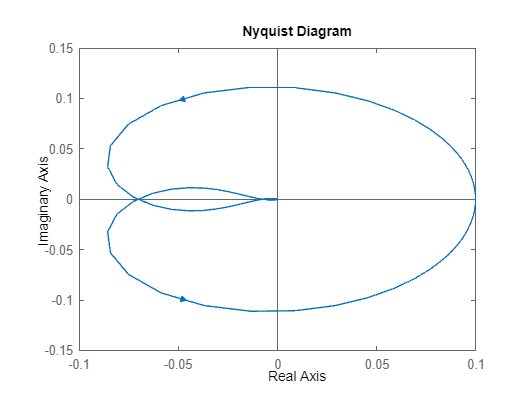

k = 1 ;
licz = k*[1 1];
mian = [0.01 0.5 3 -10 10];
G = tf(licz, mian);
h = nyquistplot(G);
%setoptions(h, 'ShowFullContour', 'off')
xlim([-0.1 0.1])
saveas(gcf,'1nyquist.png')

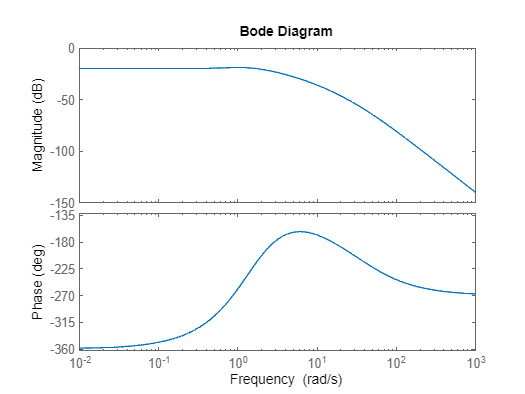


bode(G)
saveas(gcf,'1bode.png')

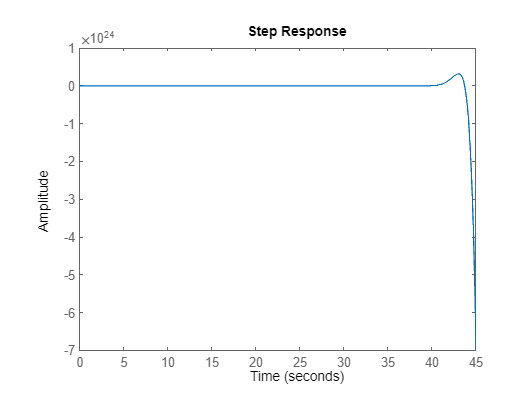


step(G)
saveas(gcf,'1step.png')


[Z, Poles, K] = tf2zp(licz, mian)

Z = -1

Poles =  -42.3443 + 0.0000i
 -10.2412 + 0.0000i
   1.2928 + 0.7966i
   1.2928 - 0.7966i


K = 100


P = length(find(roots(mian) > 0))

P = 2

#### Zadanie 2

-  $k \in (-10, 13.3), \; N=0$ --> niestabilny

- $k \in (13.3, \; 133), \; N=-2$ --> stabilny

- $k \in (-\infty, \; -10), \; N=-1$ --> niestabilny

- $k \in (133, \; \infty), \; N=0$ --> niestabilny

#### Zadanie 3

k = [50 200 -50 5];

licz1 = [1 1];
mian1 = [0.01 0.5 3 -10 10];
G1 = tf(licz1, mian1);
Gcl1 = minreal(k(1)*G1/(1+k(1)*G1)); %zamkniety
pole(Gcl1)

ans =  -45.2596 + 0.0000i
  -1.5453 + 8.8297i
  -1.5453 - 8.8297i
  -1.6499 + 0.0000i


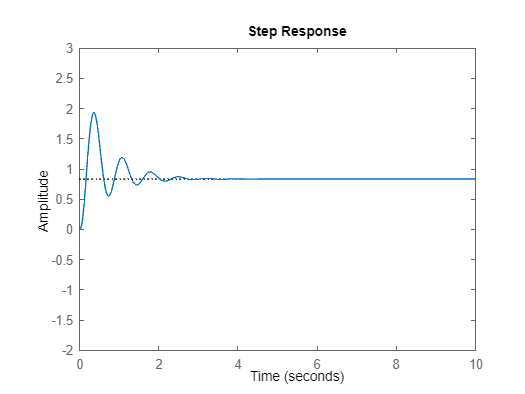

step(Gcl1)
xlim([0 10])
ylim([-2 3])
saveas(gcf,'3resp1.png')


licz2 = [1 1];
mian2 = [0.01 0.5 3 -10 10];
G2 = tf(licz2, mian2);
Gcl2 = minreal(k(2)*G2/(1+k(2)*G2)); %zamkniety
pole(Gcl2)

ans =  -51.2277 + 0.0000i
   1.1746 +19.0826i
   1.1746 -19.0826i
  -1.1215 + 0.0000i


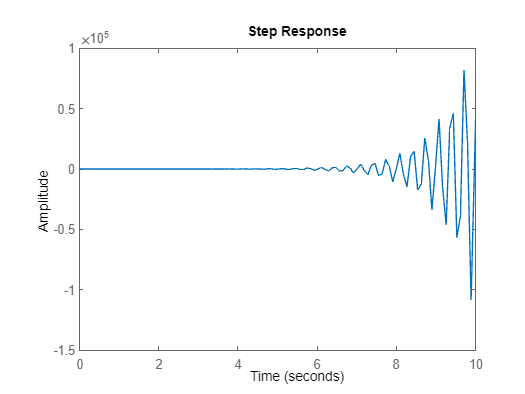

step(Gcl2)
xlim([0 10])
saveas(gcf,'3resp2.png')


licz3 = [1 1];
mian3 = [0.01 0.5 3 -10 10];
G3 = tf(licz3, mian3);
Gcl3 = minreal(k(3)*G3/(1+k(3)*G3)); %zamkniety
pole(Gcl3)

ans =   -38.0397
  -19.5949
    8.2825
   -0.6479


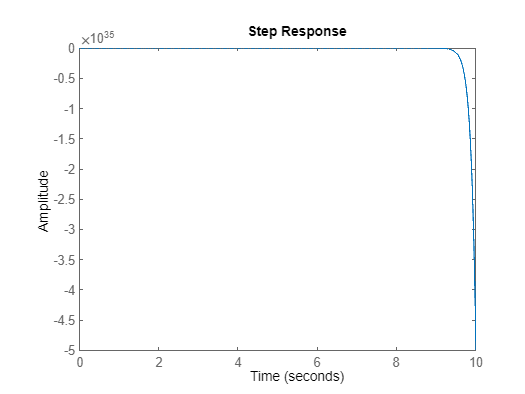

step(Gcl3)
xlim([0 10])
saveas(gcf,'3resp3.png')


licz4 = [1 1];
mian4 = [0.01 0.5 3 -10 10];
G4 = tf(licz4, mian4);
Gcl4 = minreal(k(4)*G4/(1+k(4)*G4)); %zamkniety
pole(Gcl4)

ans =  -42.6765 + 0.0000i
  -9.1208 + 0.0000i
   0.8987 + 1.7453i
   0.8987 - 1.7453i


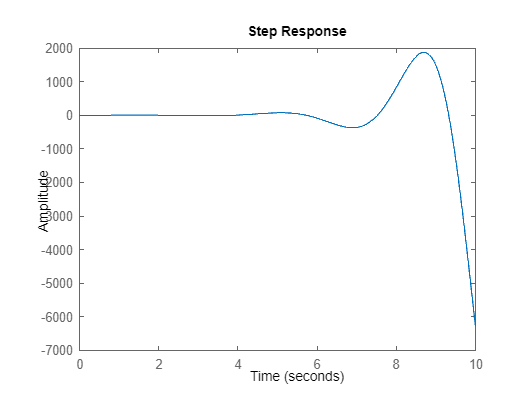

step(Gcl4)
xlim([0 10])
saveas(gcf,'3resp4.png')

####     Zadanie 4

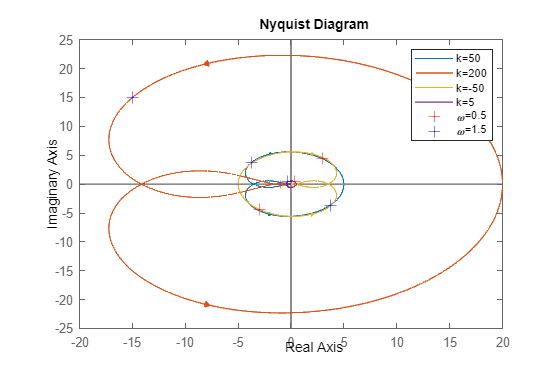

mian = [0.01 0.5 3 -10 10];
G = tf(licz, mian);

[re1_1, im1_1, wout] = nyquist(k(1)*G , 0.5 );
[re1_2, im1_2, wout] = nyquist(k(1)*G , 1.5 );
[re2_1, im2_1, wout] = nyquist(k(2)*G , 0.5 );
[re2_2, im2_2, wout] = nyquist(k(2)*G , 1.5 );
[re3_1, im3_1, wout] = nyquist(k(3)*G , 0.5 );
[re3_2, im3_2, wout] = nyquist(k(3)*G , 1.5 );
[re4_1, im4_1, wout] = nyquist(k(4)*G , 0.5 );
[re4_2, im4_2, wout] = nyquist(k(4)*G , 1.5 );

w = 0.01 : 0.01: 100;
figure ('Position', [10 10 900 600])
hold on
nyquist(k(1)*G, w)
nyquist(k(2)*G, w)
nyquist(k(3)*G, w)
nyquist(k(4)*G, w)

plot(re1_1, im1_1, 'r+', 'MarkerSize', 10)
plot(re1_2, im1_2, 'b+', 'MarkerSize', 10)
plot(re2_1, im2_1, 'r+', 'MarkerSize', 10)
plot(re2_2, im2_2, 'b+', 'MarkerSize', 10)
plot(re3_1, im3_1, 'r+', 'MarkerSize', 10)
plot(re3_2, im3_2, 'b+', 'MarkerSize', 10)
plot(re4_1, im4_1, 'r+', 'MarkerSize', 10)
plot(re4_2, im4_2, 'b+', 'MarkerSize', 10)

legend('k=50', 'k=200', 'k=-50', 'k=5', '\omega=0.5', '\omega=1.5')

hold off
saveas(gcf,'4.png')

#### Zadanie 5

#### Zadanie 6

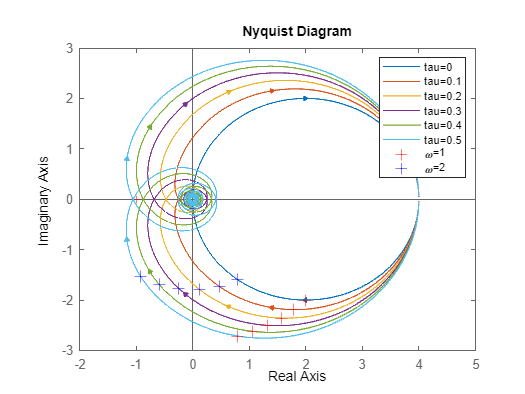

tau = [0 0.1 0.2 0.3 0.4 0.5];

G_d1 = tf(4, [1 1], 'InputDelay', tau(1));
G_d2 = tf(4, [1 1], 'InputDelay', tau(2));
G_d3 = tf(4, [1 1], 'InputDelay', tau(3));
G_d4 = tf(4, [1 1], 'InputDelay', tau(4));
G_d5 = tf(4, [1 1], 'InputDelay', tau(5));
G_d6 = tf(4, [1 1], 'InputDelay', tau(6));

[re1_1, im1_1, wout] = nyquist(G_d1, 1 );
[re1_2, im1_2, wout] = nyquist(G_d1, 2 );
[re2_1, im2_1, wout] = nyquist(G_d2, 1 );
[re2_2, im2_2, wout] = nyquist(G_d2, 2 );
[re3_1, im3_1, wout] = nyquist(G_d3, 1 );
[re3_2, im3_2, wout] = nyquist(G_d3, 2 );
[re4_1, im4_1, wout] = nyquist(G_d4, 1 );
[re4_2, im4_2, wout] = nyquist(G_d4, 2 );
[re5_1, im5_1, wout] = nyquist(G_d5, 1 );
[re5_2, im5_2, wout] = nyquist(G_d5, 2 );
[re6_1, im6_1, wout] = nyquist(G_d6, 1 );
[re6_2, im6_2, wout] = nyquist(G_d6, 2 );

w = 0.01 : 0.01: 100;
close all;
figure (2)
hold on
nyquist(G_d1, w)
nyquist(G_d2, w)
nyquist(G_d3, w)
nyquist(G_d4, w)
nyquist(G_d5, w)
nyquist(G_d6, w)

plot(re1_1, im1_1, 'r+', 'MarkerSize', 10)
plot(re1_2, im1_2, 'b+', 'MarkerSize', 10)
plot(re2_1, im2_1, 'r+', 'MarkerSize', 10)
plot(re2_2, im2_2, 'b+', 'MarkerSize', 10)
plot(re3_1, im3_1, 'r+', 'MarkerSize', 10)
plot(re3_2, im3_2, 'b+', 'MarkerSize', 10)
plot(re4_1, im4_1, 'r+', 'MarkerSize', 10)
plot(re4_2, im4_2, 'b+', 'MarkerSize', 10)
plot(re5_1, im5_1, 'r+', 'MarkerSize', 10)
plot(re5_2, im5_2, 'b+', 'MarkerSize', 10)
plot(re6_1, im6_1, 'r+', 'MarkerSize', 10)
plot(re6_2, im6_2, 'b+', 'MarkerSize', 10)

legend('tau=0', 'tau=0.1', 'tau=0.2', 'tau=0.3', 'tau=0.4', 'tau=0.5','\omega=1', '\omega=2')
xlim([-2 5])
hold off
saveas(gcf,'6.png')

#### Zadanie 7

Gcld_1 = minreal(G_d1/(1+G_d1));
Gcld_2 = minreal(G_d2/(1+G_d2));

1 state removed.


Gcld_3 = minreal(G_d3/(1+G_d3));

1 state removed.


Gcld_4 = minreal(G_d4/(1+G_d4));

1 state removed.


Gcld_5 = minreal(G_d5/(1+G_d5));

1 state removed.


Gcld_6 = minreal(G_d6/(1+G_d6));

1 state removed.


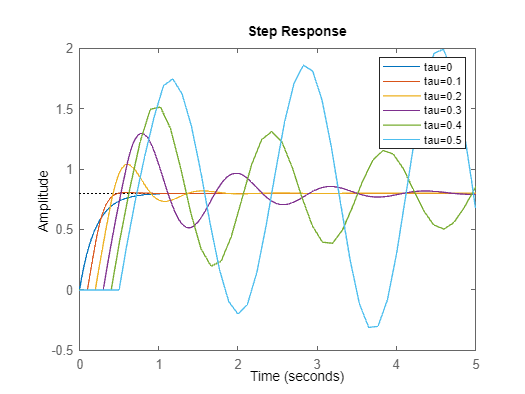


close all;
figure (3)
hold on
step(Gcld_1)
step(Gcld_2)
step(Gcld_3)
step(Gcld_4)
step(Gcld_5)
step(Gcld_6)
legend('tau=0', 'tau=0.1', 'tau=0.2', 'tau=0.3', 'tau=0.4', 'tau=0.5')
xlim([0 5])
hold off
saveas(gcf,'7.png')

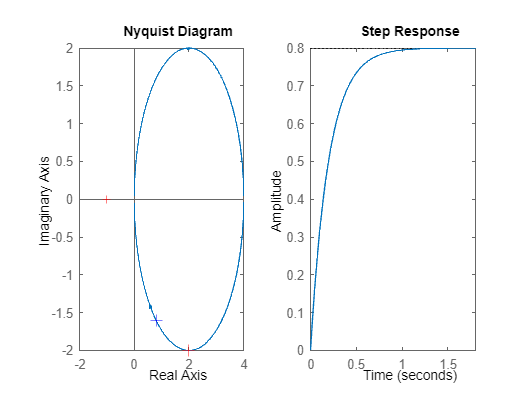

figure
subplot(1, 2, 1)
hold on
nyquist(G_d1, w)
plot(re1_1, im1_1, 'r+', 'MarkerSize', 10)
plot(re1_2, im1_2, 'b+', 'MarkerSize', 10)
hold off
subplot(1, 2, 2)
step(Gcld_1)
saveas(gcf, '7comp1.png')

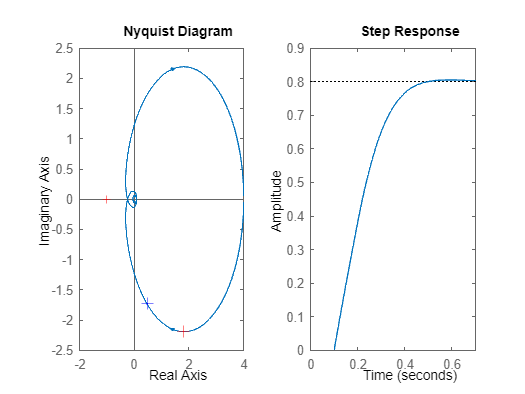


figure
subplot(1, 2, 1)
hold on
nyquist(G_d2, w)
plot(re2_1, im2_1, 'r+', 'MarkerSize', 10)
plot(re2_2, im2_2, 'b+', 'MarkerSize', 10)
hold off
subplot(1, 2, 2)
step(Gcld_2)
saveas(gcf, '7comp2.png')

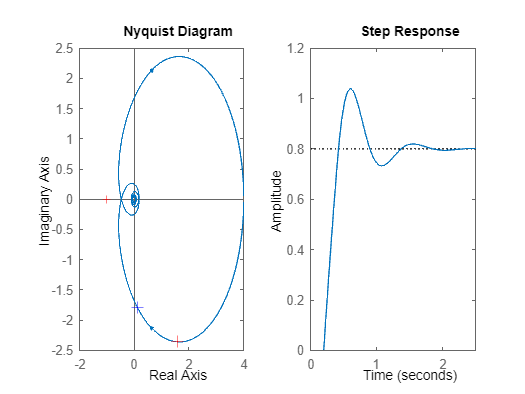


figure
subplot(1, 2, 1)
hold on
nyquist(G_d3, w)
plot(re3_1, im3_1, 'r+', 'MarkerSize', 10)
plot(re3_2, im3_2, 'b+', 'MarkerSize', 10)
hold off
subplot(1, 2, 2)
step(Gcld_3)
saveas(gcf, '7comp3.png')

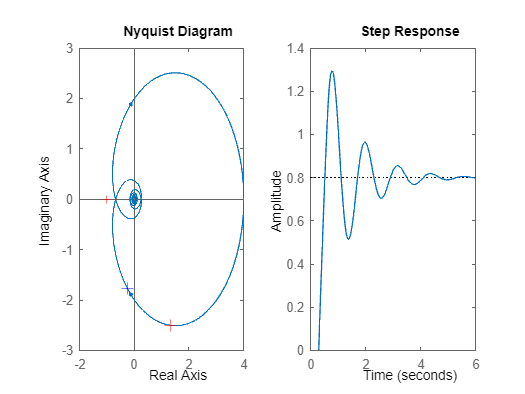


figure
subplot(1, 2, 1)
hold on
nyquist(G_d4, w)
plot(re4_1, im4_1, 'r+', 'MarkerSize', 10)
plot(re4_2, im4_2, 'b+', 'MarkerSize', 10)
hold off
subplot(1, 2, 2)
step(Gcld_4)
saveas(gcf, '7comp4.png')

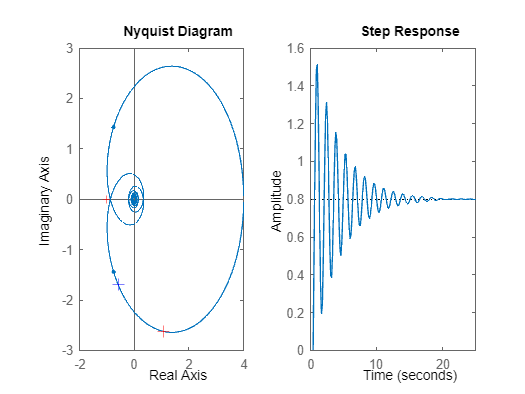


figure
subplot(1, 2, 1)
hold on
nyquist(G_d5, w)
plot(re5_1, im5_1, 'r+', 'MarkerSize', 10)
plot(re5_2, im5_2, 'b+', 'MarkerSize', 10)
hold off
subplot(1, 2, 2)
step(Gcld_5)
saveas(gcf, '7comp5.png')

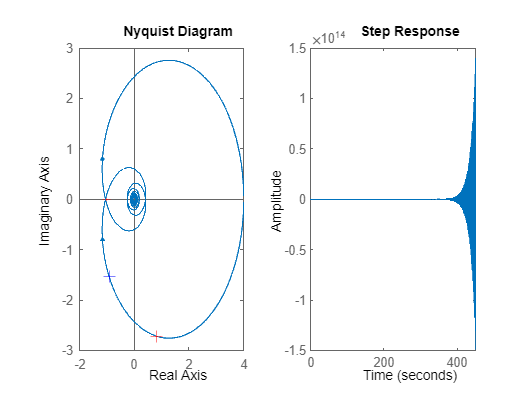


figure
subplot(1, 2, 1)
hold on
nyquist(G_d6, w)
plot(re6_1, im6_1, 'r+', 'MarkerSize', 10)
plot(re6_2, im6_2, 'b+', 'MarkerSize', 10)
hold off
subplot(1, 2, 2)
step(Gcld_6)
saveas(gcf, '7comp6.png')

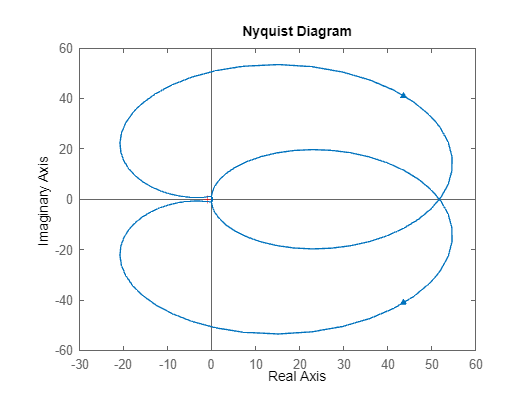

figure
licz = 50 * [1 3 42 40];
mian = [1 4 187 366 8282];
nyquist(licz, mian)

P = length(find(roots(mian) > 0))

P = 0

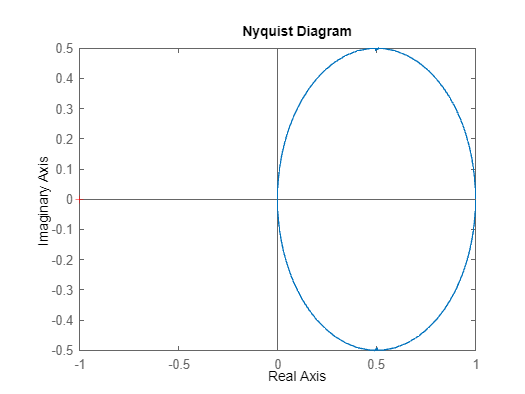


licz = [1];
mian = [1 1];
nyquist(licz, mian)

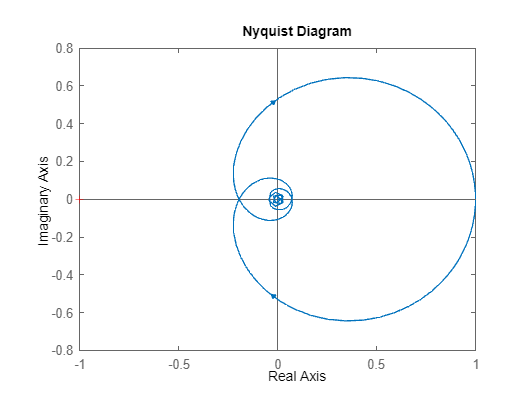

G = tf(licz, mian, 'InputDelay', pi/9);
nyquist(G)

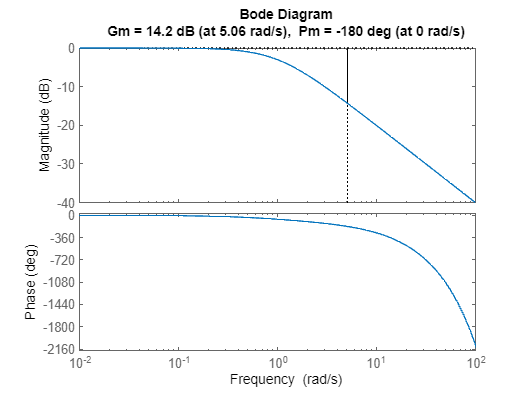

all

allmargin(G)    

ans = struct with fields:
     GainMargin: [5.1569 22.6486 40.5813 58.5574 76.5438 94.5356 112.5044]
    GMFrequency: [5.0591 22.6265 40.5689 58.5489 76.5372 94.5303 112.5000]
    PhaseMargin: -180
    PMFrequency: 0
    DelayMargin: Inf
    DMFrequency: 0
         Stable: 1


licz = 50*[1 2 4];
mian = [1 2 100 0];
G = tf(licz, mian)

G =
 
  50 s^2 + 100 s + 200
  --------------------
  s^3 + 2 s^2 + 100 s
 
Continuous-time transfer function.



P = length(find(roots(mian) > 0))

P = 0

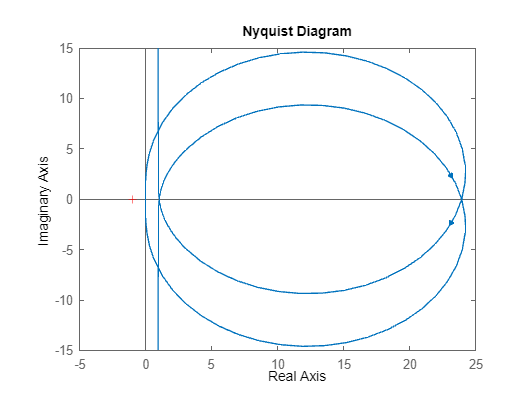

nyquist(licz, mian)

G_z = minreal(G/(1+G));
[Z, Poles, K] = tf2zp(G_z)

Not enough input arguments.

Error in tf2zp (line 36)
[nd,md] = size(den);